# Matrix Representations of Linear Systems

## Why use matrices?

Matrix representations have several useful qualities. Four are listed here.

- Matrices offer a compact representation for linear systems of equations

- Matrices are useful for representing solution algorithms to linear systems of equations

- The solvability of a linear system can be ascertained through matrix properties

- Decompositions of matrices can offer meaningful insight into the dynamics of large systems

 1. Systems with many similar parts can often benefit from a matrix representation. For example, a lumped parameter model of a blood vessel network can be represented in matrix form:

$\mathbf{C}\frac{d\mathbf{p}}{dt} = \mathbf{R}\mathbf{p}$.

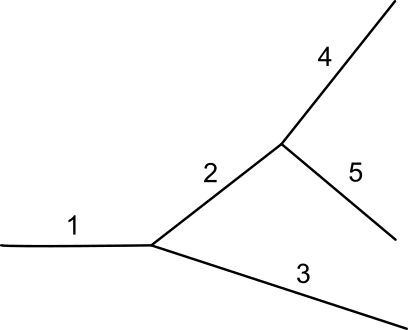

*A small vessel network*

2. Consider a linear transformation that rotates a coordinate system:

*[illustratation of a coordinate system rotation, the unused system is grayed out in both pictures, arrows between pictures are labeled with the matrix required to transform between the systems]*

The transformation from the first coordinate system to the second can be represented as

    
$$\hat\mathbf{x} = \mathbf{A} \mathbf{x}$$


If you want to reverse the transformation, you can use the matrix inverse ($\mathbf{A}^{-1}$):

    $\mathbf{x} = \mathbf{A}^{-1} \hat\mathbf{x}$.

3. A system of $n$ linear equations with $n$ variables can have a unique solution, infinite solutions, or no solutions. 

*[images of systems with unique, infinite, and no solutions]*

If you write the system in matrix form, $\mathbf{A} \mathbf{x} = \mathbf{b}$, the properties of the coefficient matrix $\mathbf{A}$ supply information on the solvability of the system.

4. Decomposing the coefficient matrix of a system, especially a system of ODEs, can offer insight into the physical dynamics of that system.

[Illustration of multiple connected masses]

This system of connected masses will vibrate in natural modes. The equations of motion can be written in matrix form $\ddot\mathbf{x} = \mathbf{Ax}$. By computing the eigenvalue decomposition of $\mathbf{A = V \Lambda V^{-1}}$, you can identify the oscillation frequencies (the eigenvalues, $\lambda$) and the shape of the modes (the eigenvectors, $\mathbf{v}$).

[animated illustration of frequencies and modes of oscillation]

## Systems of linear equations

A *system of linear equations* (also called a *linear system*) is a set of linear equations. A *linear equation* only contains terms that either multiples of variables (e.g. $1.2x$) or constants. That is, it can be expressed in the form:

     
$$a_1x_1 + a_2x_2 + a_3x_3 +  \ldots = b$$


where each $a_i$ and $b$ are constants and each $x_i$ is a variable.

**Writing a linear system in matrix form**

Consider the set of linear equations

    $\begin{array}{r}
x + y + z = 2
\\ 
x + y - z = -2
\\
ax + by + z = d
\end{array}$   (*)

where $a$ and $b$ are constants. You can write this system in matrix form, $\mathbf{Ax} = \mathbf{b}$, by defining a variable vector $\mathbf{x}$, a constant vector $\mathbf{b}$, and a coefficient matrix $\mathbf{A}$. 

Suppose that you have defined the variable vector

    
$$\mathbf{x} = \left( \matrix{x \cr y \cr z} \right)$$


what are the coefficient matrix $\mathbf{A}$ and constant vector $\mathbf{b}$?

showSolution = true;
[A,bvec] = linearEquationSltn(showSolution);

$$A = \left(\begin{array}{ccc} 1 & 1 & 1\\ 1 & 1 & -1\\ a & b & 1 \end{array}\right)$$

$$bvec = \left(\begin{array}{c} 2\\ -2\\ d \end{array}\right)$$

  **Try**

- Compute the matrix-vector product $\mathbf{Ax}$. Does the result match the LHS (left-hand side) of the linear system (*)?

**Visualize a linear system**

You can visualize 2- and 3-dimensional linear systems. For a 3-dimensional system, each equation appears as a plane. The plot below shows the linear system

   
$$\left(\begin{array}{ccc}
1 & 1 & 1\\
1 & 1 & -1\\
a & b & 1
\end{array}\right)
\left( \matrix{x \cr y \cr z} \right)
=
\left(\begin{array}{c}
2\\
-2\\
d
\end{array}\right)$$


with values specified for $a$, $b$, and $d$.

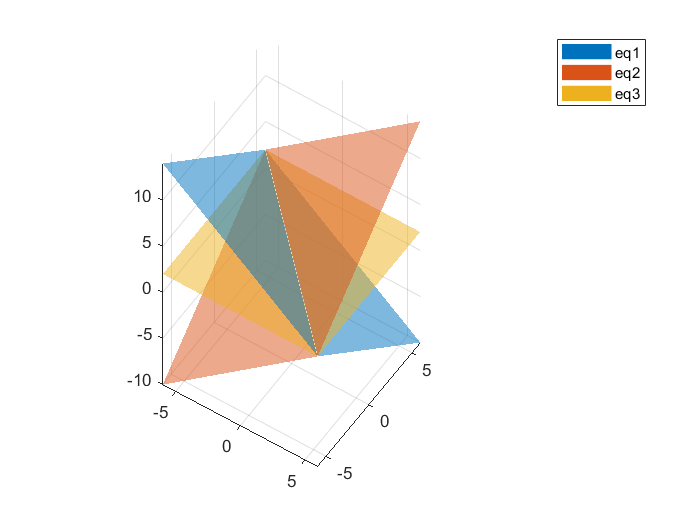

$$eq1 = x+y+z=2$$

$$eq2 = x+y-z=-2$$

$$eq3 = z=2$$

 
a = 0; % Default: 1
b = 0; % Default: -1
d = 2; % Default: -1
A = sym([1 1 1; 1 1 -1; a b 1]);
bvec = sym([2; -2; d]);
lims = [-6,6];
[eq1,eq2,eq3] = plot3DSystem(A,bvec,lims) % This function plots the planes

 **Reflect**

For each set of constants, how many solutions are there to the system?

- $a = -1$, $b = 1$, and $d = 2$

- $a = -1$, $b = -1$, and $d = -4$

- $a = 0$, $b = 0$, and $d = -4$

## Solving linear systems

#### Example: Representing a blood vessel network ODE system in terms of matrices

**Background**

A simple representation of a blood vessel is a lumped parameter model. In this model, each vessel is represented as a zero-dimensional chamber, having a pressure, compliance, and resistance to flow. Under this representation, each vessel can be represented by an **ordinary differential equation** (ODE). For a vessel with time-varying pressure $p = p(t)$:

  
$$c \frac{dp}{dt} = \text{flow in} - \text{flow out}$$


The flow in depends on the number of upstream vessels, their pressure, and resistance to flow. The flow out depends similarly on the downstream vessels. For example, if there is only one vessel upstream and downstream:

  
$$c \frac{dp}{dt} = \frac{p_{upstream} - p}{r_{in}} - \frac{p - p_{downstream}}{r_{out}}$$


Modeling a blood vessel network typically requires many equations of this form. Consider the system of 10 connected vessels shown below:

*Network of 5 connected vessels*

To describe this system, you can define variables and constants for each vessel.

- $p_i$: Pressure in the $i^{th}$ vessel

- $c_i$: Compliance of the $i^{th}$ vessel

- $r_i$: Resistance of the $i^{th}$ vessel

Under this description, the ODEs for the vessels are:

  
$$c_1 \frac{dp_1}{dt} = -\frac{p_1 - p_2}{r_1} - \frac{p_1 - p_3}{r_1}$$


  
$$c_2 \frac{dp_2}{dt} = \frac{p_1 - p_2}{r_1} - \frac{p_2 - p_4}{r_2} - \frac{p_2 - p_5}{r_2}$$


  
$$c_3 \frac{dp_3}{dt} = \frac{p_1 - p_3}{r_1}$$


  
$$c_4 \frac{dp_4}{dt} = \frac{p_2 - p_4}{r_2}$$


  
$$c_5 \frac{dp_5}{dt} = \frac{p_2 - p_5}{r_2}$$


Note that some standard parts of the system have been neglected for simplicity.

**Matrix representation **

Defining the vector 


$$\mathbf{p} = \left[ \matrix{p_1 \cr p_2 \cr p_3 \cr p_4 \cr p_5 }\right]$$


allows the solution to be written in matrix form as


$$\mathbf{C}\frac{d\mathbf{p}}{dt} = \mathbf{R}\mathbf{p}$$


where the matrices $\mathbf{C}$ and $\mathbf{R}$ contain the compliances and connectivity with resistances, respectively:

$\mathbf{C} = \left( \matrix{ 
c_1 & 0 & 0 &  0 & 0 
 \cr
 0 & c_2 & 0  & 0 & 0
 \cr 
0 & 0 & c_3 & 0 & 0
 \cr 
0 & 0 & 0 & c_4 & 0
\cr
0 & 0 & 0 & 0 & c_5
}\right)$,    $\mathbf{R} = \left( \matrix{ 
-2/r_1 & 1/r_1 & 1/r_1 &  0  & 0
\cr
1/r_1 & - 1/r_1 - 2/r_2 & 0 & 1/r_2 & 1/r_2
\cr 
1/r_1 & 0 & - 1/r_1 & 0 & 0
\cr 
0 & 1/r_2 & 0 & -1/r_2 & 0
\cr
0 & 1/r_2 & 0 & 0 & -1/r_2
}\right)$

Notice that the matrix $\mathbf{R}$ encapsulates two physical features: the connectivity of the blood vessels and their resistance.

function [A,bvec] = linearEquationSltn(showSolution)
    A = [];
    bvec = [];
    if(showSolution)
        syms a b d
        A = sym([1 1 1; 1 1 -1; a b 1])
        bvec = sym([2; -2; d])
    end
end

function [eq1,eq2,eq3] = plot3DSystem(A,bvec,lims)
    % Solve for z
    syms x y z;
    xvec = [x; y; z];
    eqs = A*xvec == bvec;
    eq1 = eqs(1);
    eq2 = eqs(2);
    eq3 = eqs(3);
    f1 = solve(eq1,z);
    f2 = solve(eq2,z);
    f3 = solve(eq3,z);
    % Create the plot
    c = lines(5);
    fsurf(f1,lims,"facecolor",c(1,:),"facealpha",0.5,"edgecolor","none")
    hold on;
    fsurf(f2,lims,"facecolor",c(2,:),"facealpha",0.5,"edgecolor","none")
    fsurf(f3,lims,"facecolor",c(3,:),"facealpha",0.5,"edgecolor","none")
    hold off
    axis equal;
    view (10,30); 
    axis tight
    legend("eq1","eq2","eq3")
    
    
end